%load toy2.dat
N = 4 % number of data points

N = 4

I = 3 % dimension of data (dimension of each data point) (it is 2 but 

I = 3

% here setting it to 3 to account for weights biases)

% Data points
xp1 = [1 4]; % red (class 0)
xp2 = [3 2]; % blue (class 1)
xp3 = [3 5]; % blue (class 1)
xp4 = [7 3] ;% red (class 0)

% the N x I data matrix
X = [xp2; xp3; xp1; xp4];
X = [ones(1, N); X']' % adding ones to account for weight biases

X =      1     3     2
     1     3     5
     1     1     4
     1     7     3



% Set class 1 = blue, class 0 = red
targets = [0 1 1 0]'; % the N x 1 vector

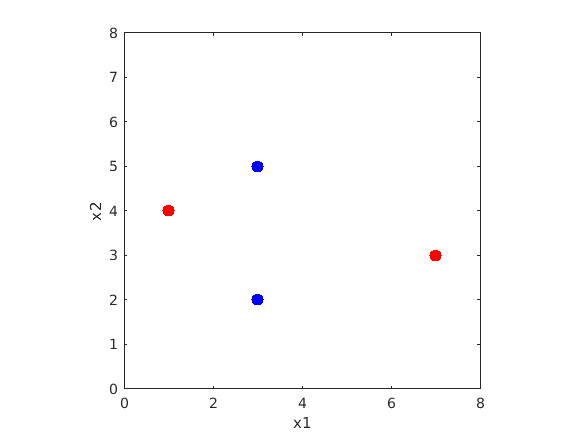

% Plot the data
figure(1); clf
plot(X(1:2, 2), X(1:2, 3), 'b.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(3:4, 2), X(3:4, 3), 'r.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 8]); ylim([0 8]); 
xlabel('x1'); ylabel('x2')
axis square
hold on

numHiddenUnits = 30

numHiddenUnits = 30


[Whidden, Wout] = errorBackpropTwoLayer(X, numHiddenUnits, targets);
Whidden

Whidden =    -0.0832   -0.2925    0.2895
    0.1435    0.4654   -0.4494
    0.0659    0.2261   -0.2309
    0.1150    0.3806   -0.3708
    0.0268    0.0973   -0.1149
   -0.0649   -0.2319    0.2354
    0.0027    0.0101   -0.0100
   -0.1475   -0.4774    0.4606
   -0.1368   -0.4517    0.4361
    0.0747    0.2576   -0.2588


Wout

Wout =    -0.1930    0.4491   -0.7867   -0.3447   -0.6075   -0.1552    0.3525   -0.0142    0.8153    0.7539   -0.3935    0.4061    0.0429   -0.0585    0.0462    0.3923   -0.0257    0.1782   -0.6154    0.8142    0.5514   -0.0217    0.6870    0.2744    0.0474   -0.3910    0.3334   -0.0559   -0.2208    0.8153    0.2812




 % Calculate learned values
learnedY = @(X) sigmoid(Wout * [ones(1, 10000); tanh(Whidden * X')]) ; %yFunc(Whidden, Wout, 10000);

x1 = linspace(0, N);
x2 = x1; 
[x1 x2] = meshgrid(x1, x2);
xs = [ones(10000, 1), x1(:), x2(:)];

learnedY_values = learnedY(xs)

learnedY_values =     0.2110    0.2366    0.2644    0.2943    0.3262    0.3598    0.3949    0.4312    0.4682    0.5056    0.5429    0.5797    0.6155    0.6501    0.6831    0.7142    0.7434    0.7704    0.7952    0.8179    0.8385    0.8570    0.8737    0.8885    0.9017    0.9134    0.9238    0.9329    0.9410    0.9480    0.9542    0.9597    0.9645    0.9686    0.9723    0.9755    0.9783    0.9808    0.9830    0.9849    0.9865    0.9880    0.9893    0.9904    0.9914    0.9923    0.9931    0.9938    0.9944    0.9950


size(learnedY_values)

ans =            1       10000


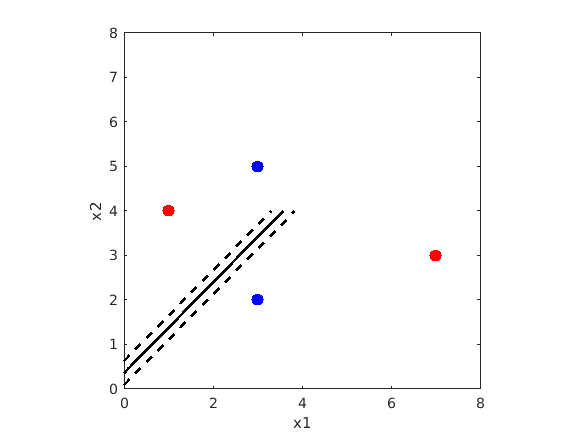



figure(1); clf
plot(X(1:2, 2), X(1:2, 3), 'b.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(3:4, 2), X(3:4, 3), 'r.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 8]); ylim([0 8]); 
xlabel('x1'); ylabel('x2')
axis square
hold on
contour(x1 ,x2, reshape(learnedY_values, 100, 100), [0.27, 0.73], '--k', 'LineWidth', 2); hold on
contour(x1 ,x2, reshape(learnedY_values, 100, 100), [0.5, 0.5], 'k', 'LineWidth', 2); 